% image
imageFolder = 'imagemitsuba/pla_0.225/';
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更
imgcnt = 6;
matFilePath = fullfile(imageFolder, imageFiles(imgcnt).name);
data = load(matFilePath);
% luminance adjust
luminanceFolder = 'luminance_adjust/';
lumFiles = dir(fullfile(luminanceFolder,'*.mat'));
lumFilePath = fullfile(luminanceFolder,"Three_Lum_cu_0.025.mat");
lumdata = load(lumFilePath);
%color space
cform1 = makecform('xyz2xyl')

cform1 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyl2xyz')

cform2 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---Input xyY---
%{
xyYImgin = data.image_np_xyY; 
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
lum_av = mean(xyYImgin(:))
disp(lum_av)

xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input xyY---xyYImgin(:,:,3)
%---Input XYZ---
%{
xyzImgin = data.image_np_XYZ_900;
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input XYZ---
%---Input XYZ 2---

lumlist = lumdata.ImagesLumData;
three_lum = lumlist(imgcnt).Luminance;

xyzImgin = double(data.image_XYZ);
xyYImgin = applycform(xyzImgin,cform1);
Ychan_TMO = Reinhard(xyYImgin(:,:,3),10.0);
lum_av = mean(Ychan_TMO(:));
Y_Scale = Ychan_TMO*100*three_lum/lum_av;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),Y_Scale);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);

disp(three_lum);

    0.1793



disp(lum_av)

    0.1352



%{
figure;
histogram(Ychan_TMO(:), 'Normalization', 'probability','NumBins',5000);
title('Mitsuba linear non-tonemap');
xlabel('輝度値');
ylabel('頻度(正規化)');
xlim([-1,5]);
%}
rgbImgcom = gamma_converter.digital_rgb_to_linear_rgb(digital_rgb);
xyzImgcom = c.linear_rgb_to_xyz(rgbImgcom);
%xyzImgcom = rgb2xyz(digital_rgb);
xyYImgcom = applycform(xyzImgcom,cform1);
Ychan_com = xyYImgcom(:,:,3);
lum_av_com = mean(Ychan_com(:)/100);
disp(lum_av_com);

    0.1793



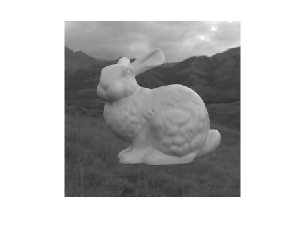

%{
figure;
histogram(Ychan_com(:), 'Normalization', 'probability');
title('Mitsuba non-linear tone-mapped ');
xlabel('輝度値');
ylabel('頻度(正規化)');
%}
%---Input XYZ 2---
%---Input rgb---
%{
rgbImgin = data.rgb_data;
xyzImgin = rgb2xyz(rgbImgin);
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input rgb---

% confirm
xyzImgin = applycform(xyYImgin,cform2);
rgbImgin = xyz2rgb(xyzImgin);
rgbImgout = xyz2rgb(xyzImgout);
imshow(rgbImgin);

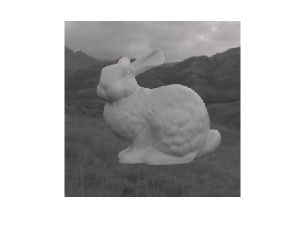

imshow(digital_rgb);

imshow(rgbImgout);